# Clustersize Inference Tutorial

To run this tutorial you first need to add all functions in the StatBrainz toolbox to the matlab path.

statsbrainz_pathloc = '';
addpath(genpath(statsbrainz_pathloc));

    10
    20
    30
    40
    50
    60
    70
    80


Load in the mask:

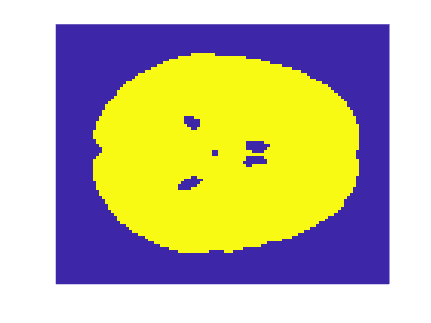

figure
MNImask = imgload('MNImask');
imagesc(squeeze(MNImask(:,:,45)))
axis off

Generate realistic data

sb_dir = statbrainz_maindir;
load([sb_dir, '/BrainImages/Real_data/hcpWM'])
nsubj = 80;
FWHM = 5;
data = gen_noise(mask, FWHM, nsubj, data_mean, data_std);

Calculate the t-statistic:

figure; set(gcf,'Visible','on')
tstat_full = mvtstat(data);
mask = ~isnan(tstat_full).*MNImask;
tstat_orig = zero2nan(tstat_full.*mask);
slice = 45;
viewdata(tstat_orig(:,:,slice), mask(:,:,slice))

ans =   Image with properties:

           CData: [109×91×3 double]
    CDataMapping: 'scaled'

  Show all properties

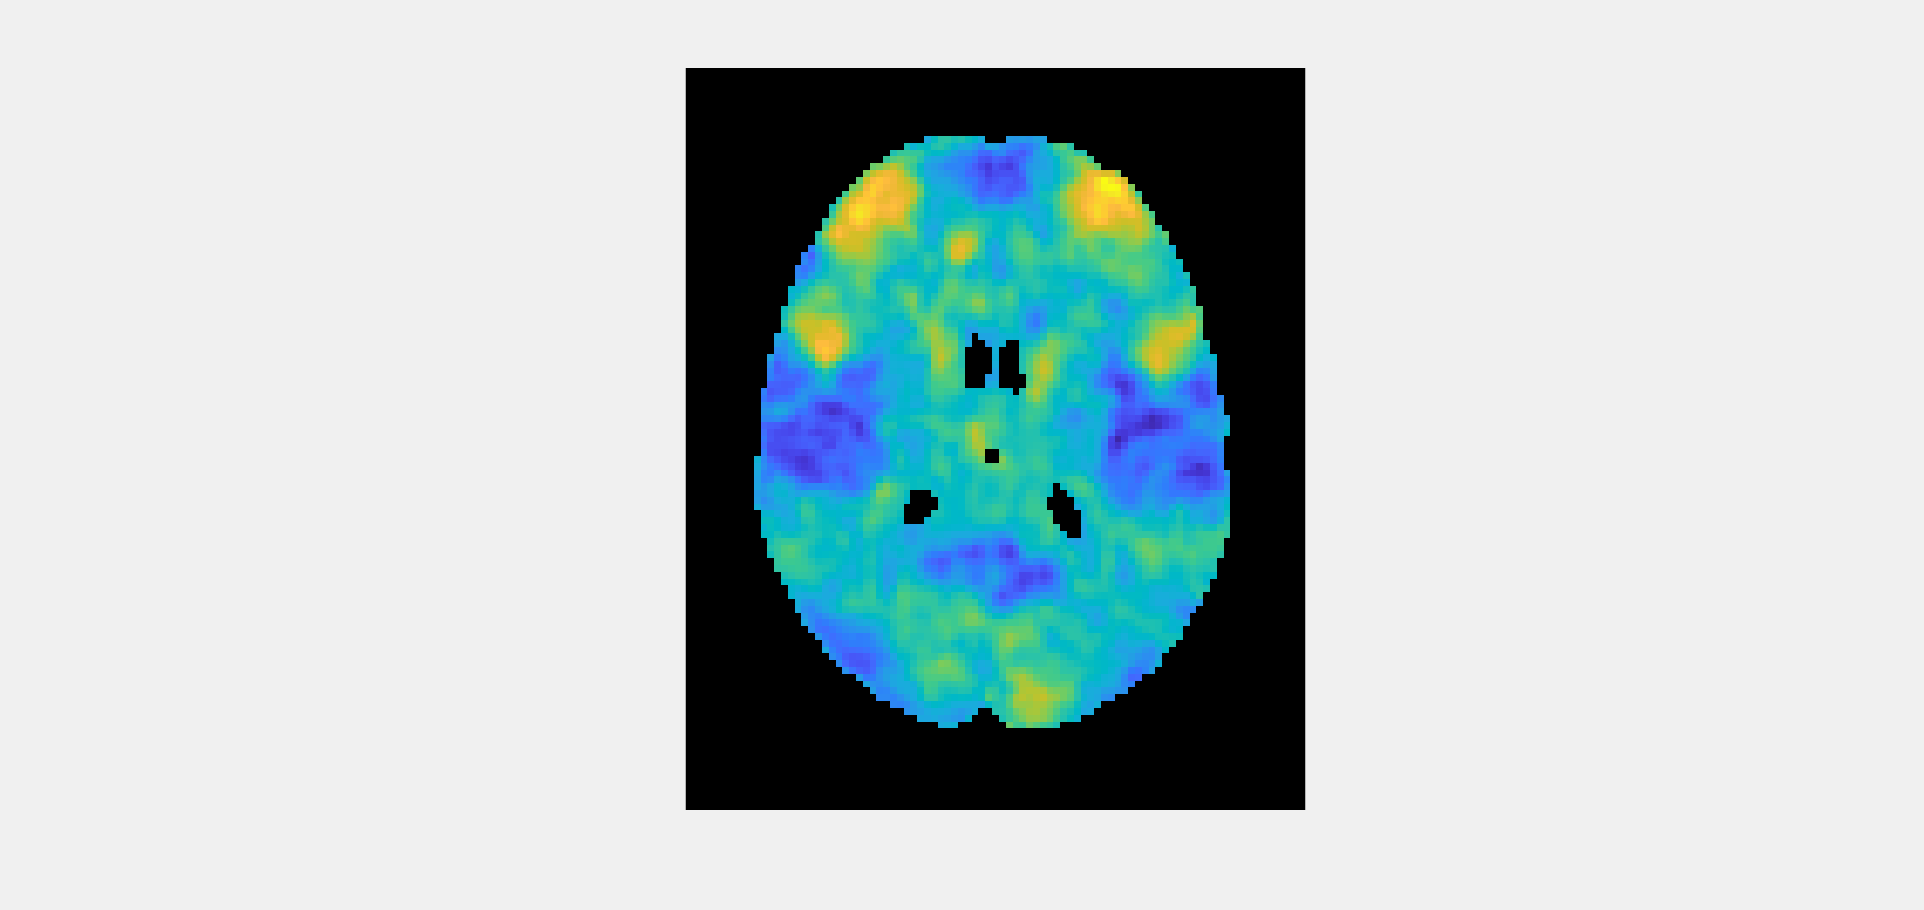

axis image
fullscreen

### View super-threshold clusters

View axial slice

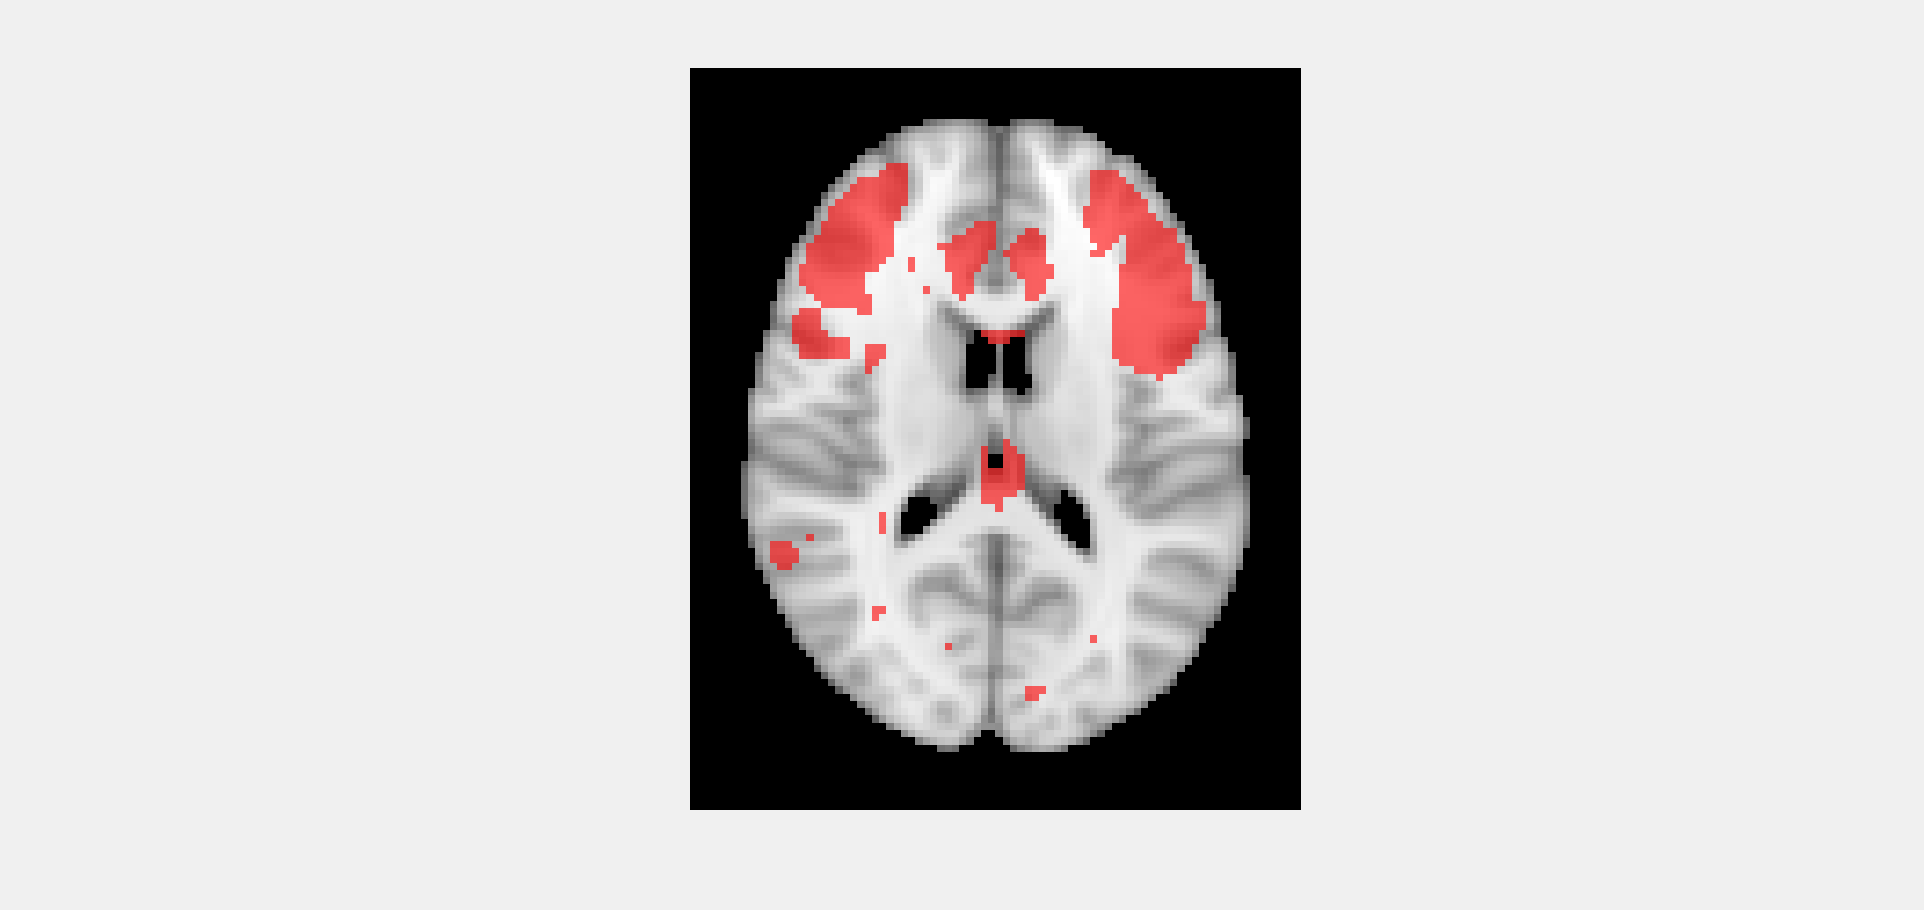

figure; set(gcf,'Visible','on')
CDT = 2.3; 
slice = 45;
overlay_brain( [0,0,slice], 6, {tstat_orig(:,:,50) > CDT}, {'red'}, 0.6, 4);

View coronal slice

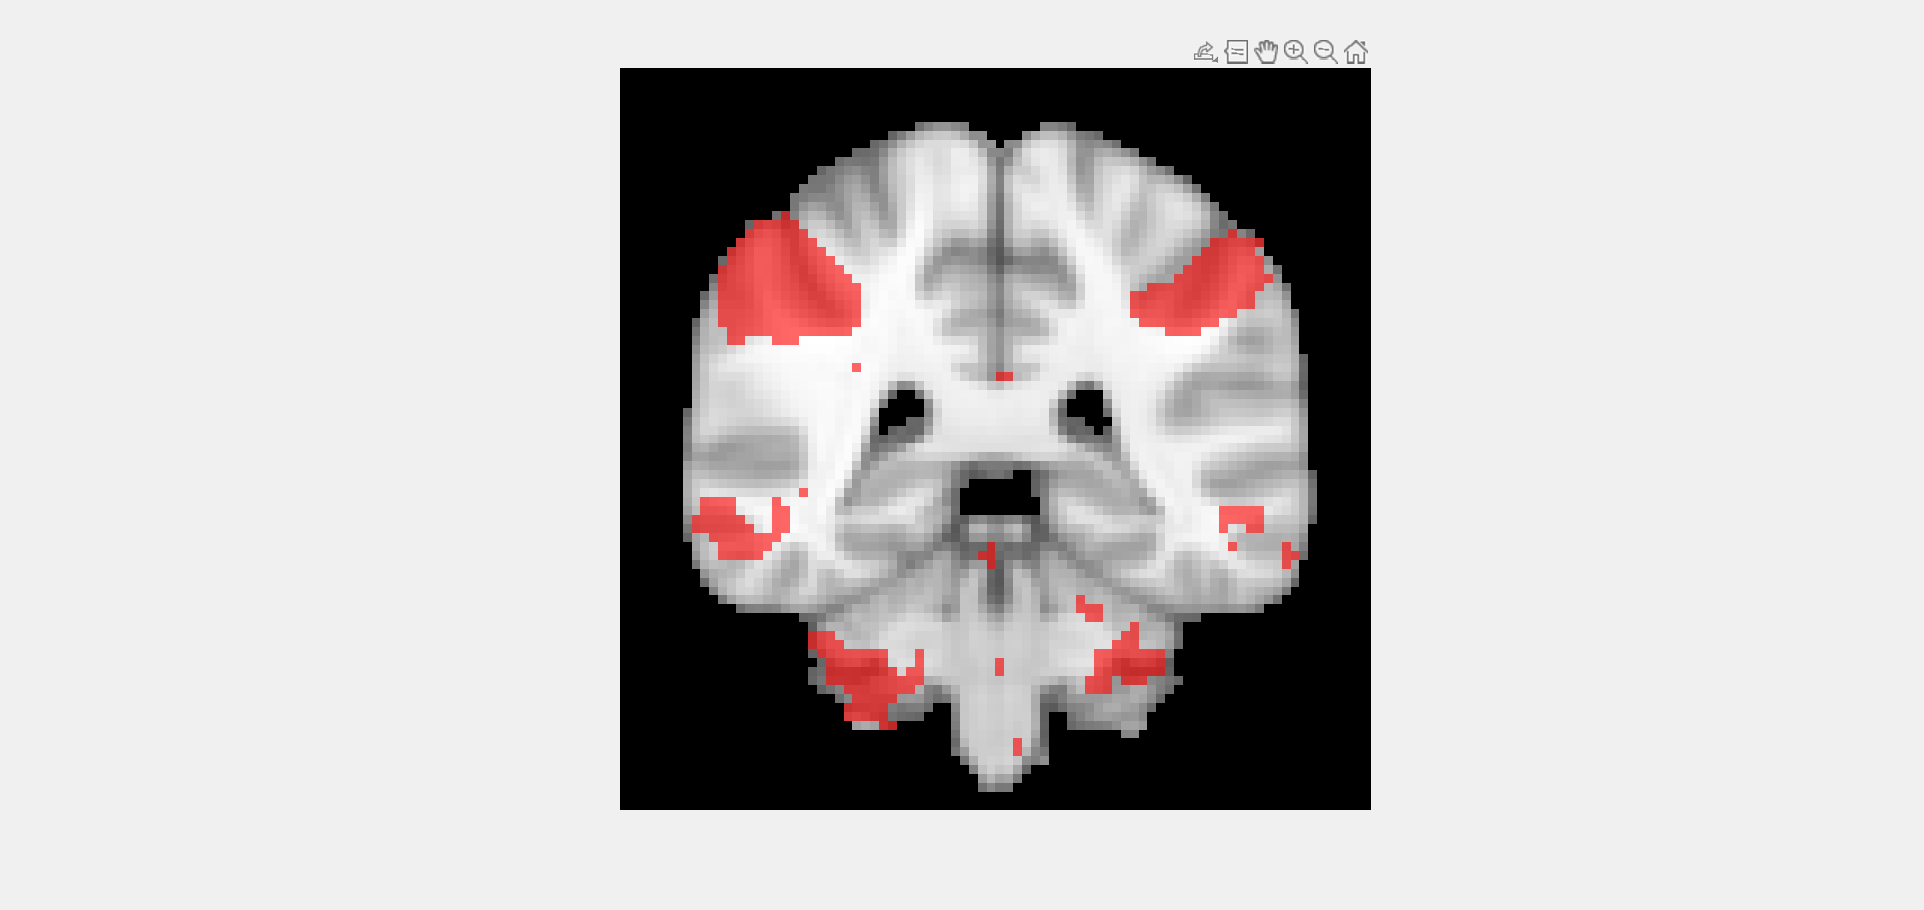

figure; set(gcf,'Visible','on')
overlay_brain( [0,slice,0], 6, {squeeze(tstat_orig(:,slice,:)) > CDT}, {'red'}, 0.6, 4);

## Permutation based clustersize inference

Clustersize inference is based on the idea that the larger the cluster, the more likely it is to correspond to a true area of activation. However even random noise can have superthreshold clusters e.g.:

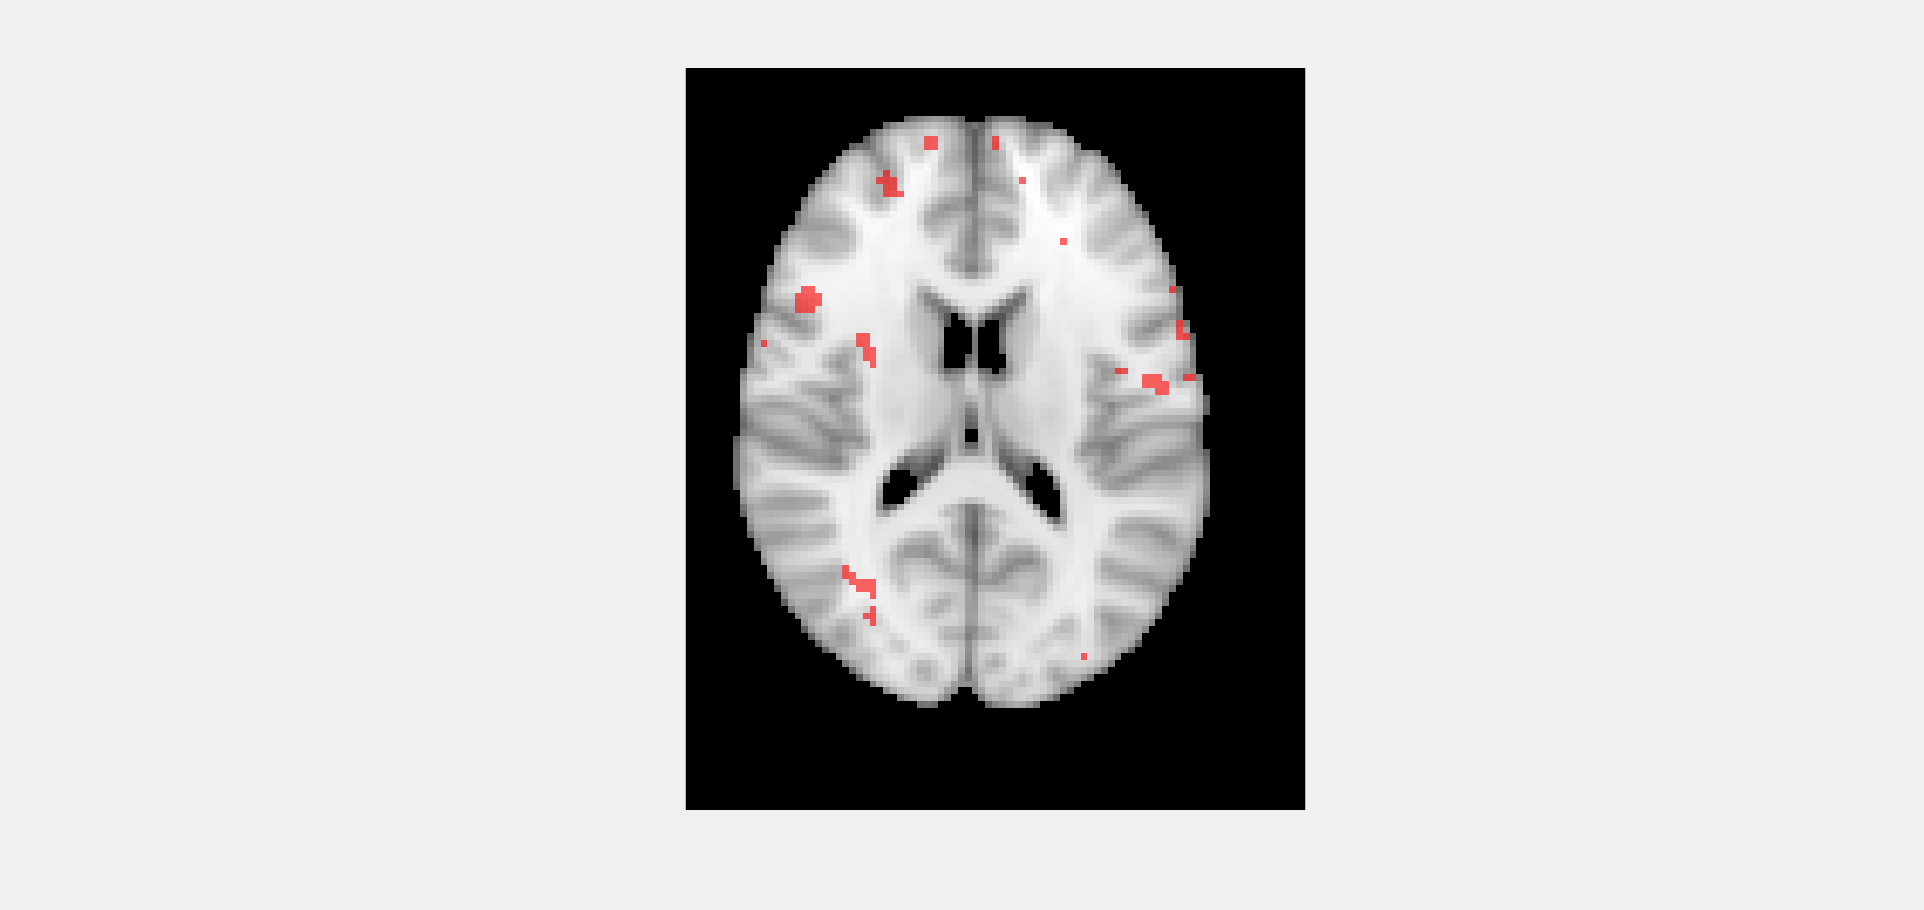

figure; set(gcf,'Visible','on')
noise_im = randn([91,109,91]).*mask;
FWHM = 3;
[smooth_noise_im, ss] = fconv(noise_im, FWHM, 3);
smooth_noise_im = smooth_noise_im/sqrt(ss);
viewdata(smooth_noise_im(:,:,slice), mask(:,:,slice));
overlay_brain( [0,0,slice], 6, {smooth_noise_im(:,:,50) > 2.3}, {'red'}, 0.6, 4);

In order to distinguish clusters of the noise from clusters of signal we can use the distribution of the maximum clustersize in order to control the familywise error rate (FWER) over clusters. In particular suppose that we observe m clusters of sizes c_1, ..., c_m, given a particular connectivity criterion. 

Then let $c_{\max} = \max_{1 \leq i \leq m} c_i$. Then given $\alpha
$, if we knew the distribution of $c_\max
$ we could take the (1-$\alpha
$)% quantile of that distribution say $q$ and reject cluster $i$ if $c_i > q$.

BUT we don't know this distribution. Instead we can estimate this using permutation testing.

connectivity_criterion = 26;
q = perm_cluster(data, mask, CDT, connectivity_criterion)

-------------------------------------------------------
perm progress: 100.0


[number_of_clusters, occurences, sizes, index_locations] = numOfConComps(tstat_orig, CDT, connectivity_criterion);
[ surviving_cluster_im, surviving_clusters, surviving_clusters_vec] = cluster_im( size(mask), index_locations, q );


## Cluster TDP

Clustersize inference has long suffered from a spatial specificity paradox. That's because the correct interpretation of a discovered signficant cluster is that "at least one voxel within it is active". The trouble is that most fMRI practitioners instead present the results as if all discovered voxels were found to be active. 

Recently, Goeman et al showed that its actually possible to provide a lower bound on the proportion of active voxels within each cluster. 